3(a)

stat = readtable("UCLA_EE_grad_2030.csv")

stat = 100×3 table
     Var1       Var2      Var3
    _______    _______    ____

     1.3464     1.0473     -1 
     1.3085     2.9918     -1 
     1.4178     1.7215     -1 
     2.9011     1.9453     -1 
      2.778     2.1079     -1 
    0.83459    0.84684     -1 
     2.0923     1.2631     -1 
     2.2634     1.6337     -1 
     1.2915     1.5779     -1 
     3.2171      1.604     -1 
     2.9454     1.6665     -1 
     2.1562     1.4961     -1 
     1.2047     2.1377     -1 
     1.2483     1.1196     -1 
     1.3581     2.1177     -1 
     1.6604     1.7785     -1 


x = stat{:,1:2};
y = (stat{:,3} + 1) / 2;
N = length(y);

admit = x(y == 1,:);
rejec = x(y == 0,:);

P0 = length(rejec) / N;
mu0 = mean(rejec);
mu1 = mean(admit);
mu = [mu0; mu1];

P0

P0 = 0.7900

mu0

mu0 =     1.8678    1.9673


mu1

mu1 =     3.1637    2.9590



covar = zeros(2, 2);
for i = 1:N
    covar = covar + (x(i,:) - mu(y(i) + 1,:))' * (x(i,:) - mu(y(i) + 1,:));
end
covar = covar / N;

covar

covar =     0.4457    0.0731
    0.0731    0.4745



w = covar \ (mu0' - mu1')

w =    -2.6314
   -1.6845


b = -0.5 * (mu0 / covar * mu0' - mu1 / covar * mu1') + log(P0) - log(1 - P0)

b = 12.0941

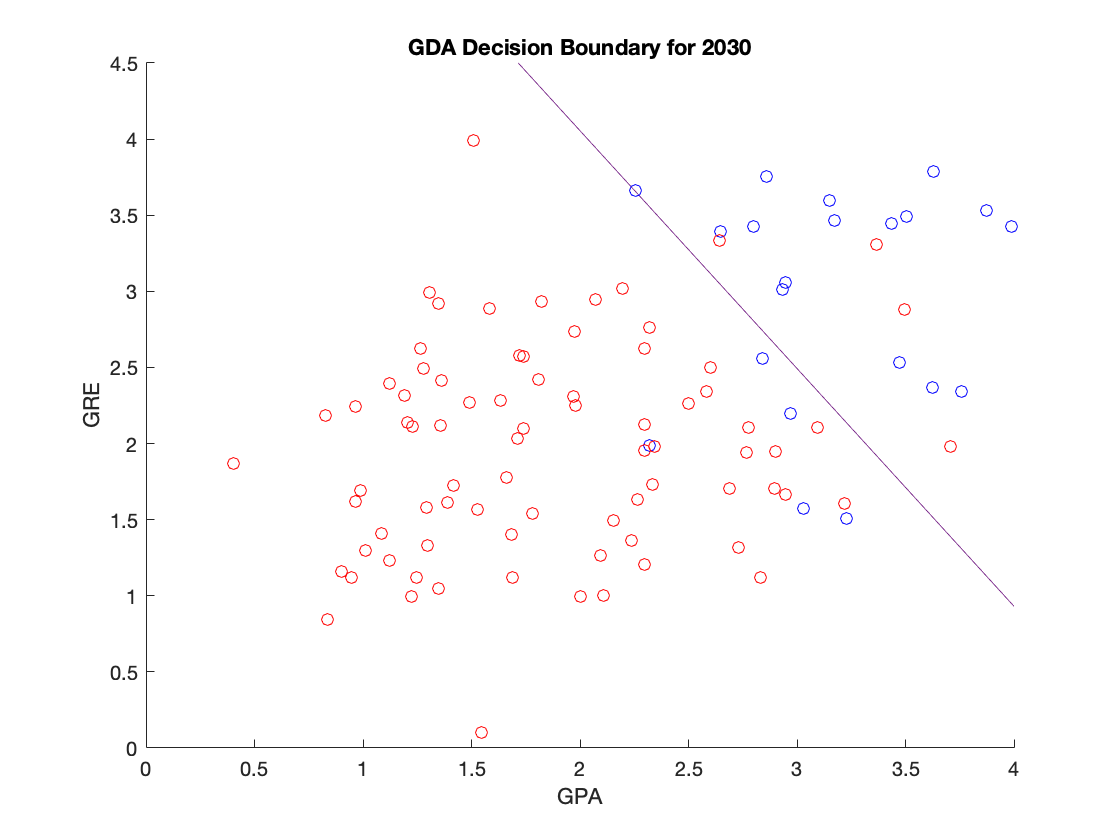


xval = 0:0.1:4;
yval = 0:0.1:4;
figure(1);
hold on;
plot(xval, -1 / w(2) * (w(1) * xval + b));
ylim([0 4.5]);
scatter(admit(:,1), admit(:,2), 'blue');
scatter(rejec(:,1), rejec(:,2), 'red');
title('GDA Decision Boundary for 2030');
xlabel('GPA');
ylabel('GRE');

(c)

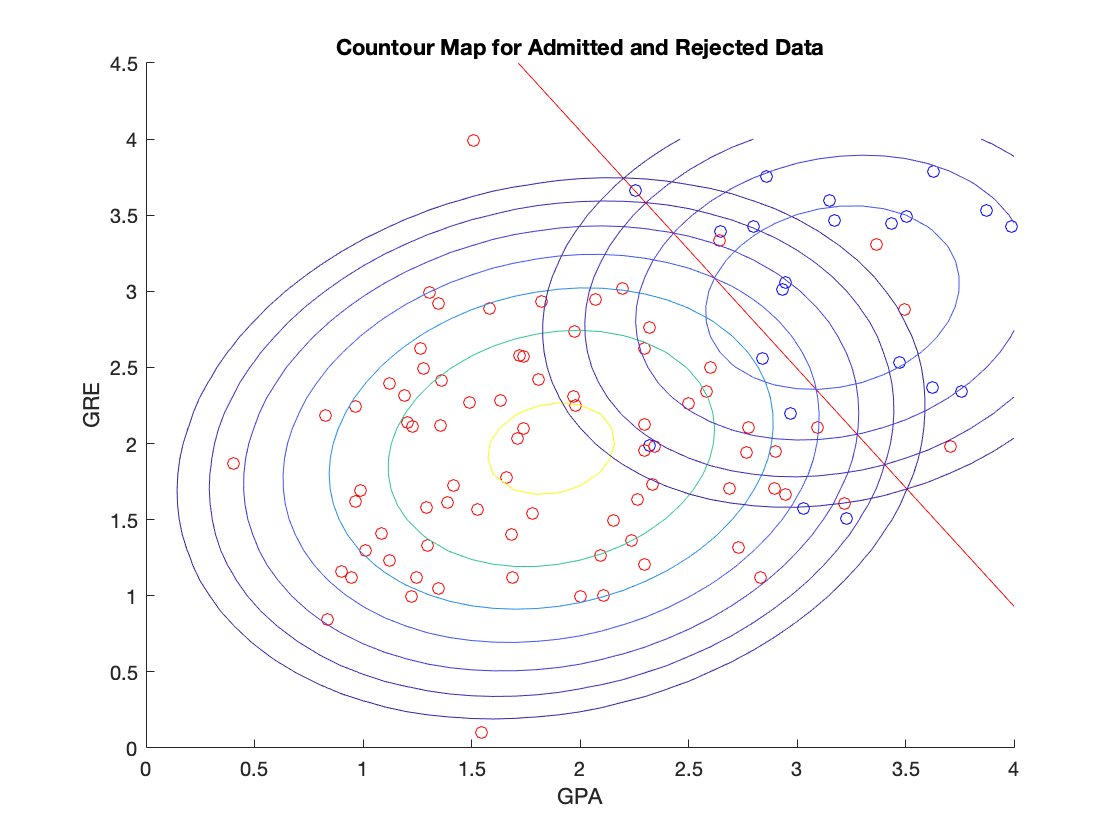

M = length(xval);
[GPA, GRE] = meshgrid(xval, yval);

Z0 = zeros(M);
Z1 = zeros(M);
for i = 1:M
    for j = 1:M
        k = [GPA(i, j); GRE(i, j)];
        Z0(i, j) = P0 * mvnpdf(k, mu0', covar);
        Z1(i, j) = (1 - P0) * mvnpdf(k, mu1', covar);
    end
end

figure(2);
hold on;
scatter(admit(:,1), admit(:,2), 'blue');
scatter(rejec(:,1), rejec(:,2), 'red');
plot(xval, -1 / w(2) * (w(1) * xval + b), 'red');
contour(GPA, GRE, Z0, 'LevelList', logspace(-2, -0.6, 7));
contour(GPA, GRE, Z1, 'LevelList', logspace(-2, -0.6, 7));
ylim([0 4.5]);

title('Countour Map for Admitted and Rejected Data');
xlabel('GPA');
ylabel('GRE');